# LAPLACE TRANSFORM

clc; clear all; 
syms s t
d = 4*cos(2*t+45);
D = expand(d)

$$D = 8\,\cos\left(45\right)\,{\cos\left(t\right)}^{2}-8\,\sin\left(45\right)\,\sin\left(t\right)\,\cos\left(t\right)-4\,\cos\left(45\right)$$

q = solve(D)

$$q = \begin{array}{l} \left(\begin{array}{c} -\log\left(-\sigma_{2}\right)\,\mathrm{i}\\ -\log\left(\sigma_{1}\right)\,\mathrm{i}\\ -\log\left(-\sigma_{1}\right)\,\mathrm{i}\\ -\log\left(\sigma_{2}\right)\,\mathrm{i} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{-\frac{{\mathrm{e}}^{-90\,\mathrm{i}}\,\left({\mathrm{e}}^{90\,\mathrm{i}}-2\,\cos\left(45\right)\,{\mathrm{e}}^{45\,\mathrm{i}}-\sqrt{-\left(2\,{\mathrm{e}}^{45\,\mathrm{i}}-{\mathrm{e}}^{90\,\mathrm{i}}+2\,\cos\left(45\right)\,{\mathrm{e}}^{45\,\mathrm{i}}-1\right)\,\left(2\,{\mathrm{e}}^{45\,\mathrm{i}}+{\mathrm{e}}^{90\,\mathrm{i}}-2\,\cos\left(45\right)\,{\mathrm{e}}^{45\,\mathrm{i}}+1\right)}+1\right)}{2}}\\ \sigma_{2}=\sqrt{-\frac{{\mathrm{e}}^{-90\,\mathrm{i}}\,\left({\mathrm{e}}^{90\,\mathrm{i}}-2\,\cos\left(45\right)\,{\mathrm{e}}^{45\,\mathrm{i}}+\sqrt{-\left(2\,{\mathrm{e}}^{45\,\mathrm{i}}-{\mathrm{e}}^{90\,\mathrm{i}}+2\,\cos\left(45\right)\,{\mathrm{e}}^{45\,\mathrm{i}}-1\right)\,\left(2\,{\mathrm{e}}^{45\,\mathrm{i}}+{\mathrm{e}}^{90\,\mathrm{i}}-2\,\cos\left(45\right)\,{\mathrm{e}}^{45\,\mathrm{i}}+1\right)}+1\right)}{2}} \end{array}$$


b = sym2poly(D)

Error using sym/sym2poly (line 30)
Not a polynomial.

f = factor(D)

L = laplace(d);
simplifyFraction(L)
fprintf('Partial fraction')
partfrac(L)

#### STABILITY

B = isstable(L)
iL = ilaplace(L)

## POLES AND ZEROS

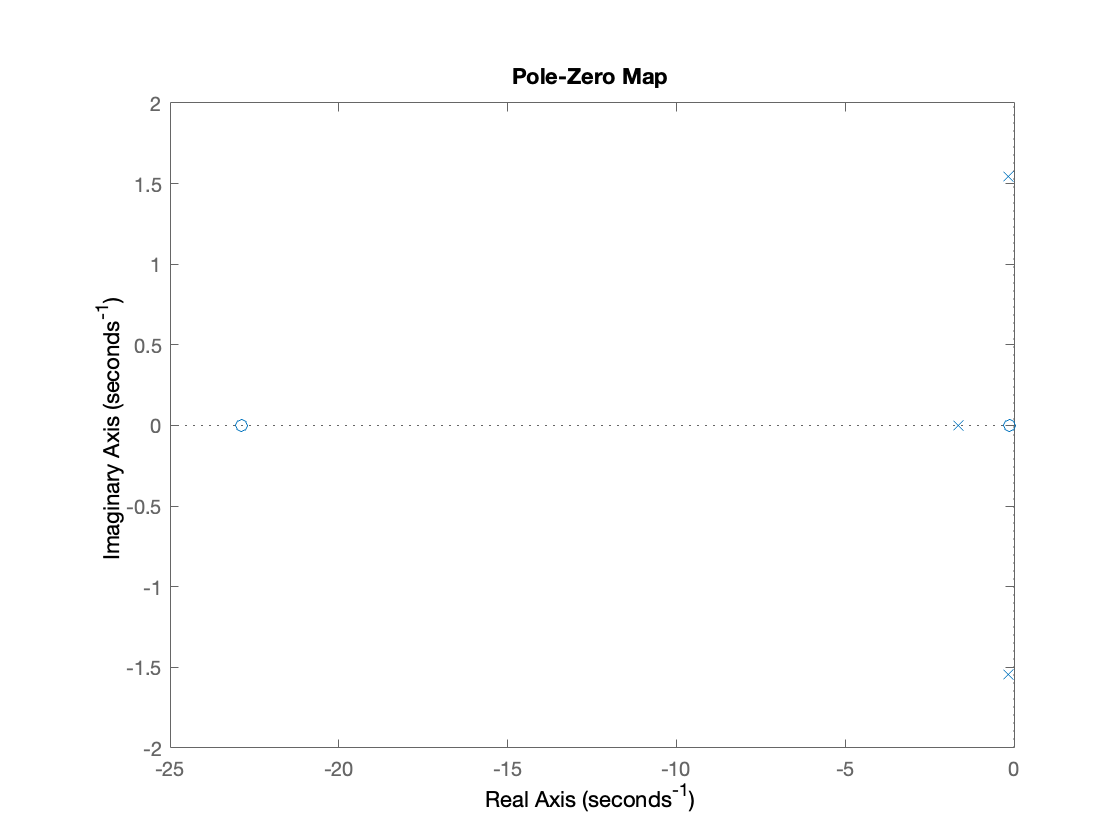

n = [1 23 3];
d = [1 2 3 4];
T = tf(n,d);
pzplot(T, '^r')

# INVERSE LAPLACE

clc; clear all; 
syms s
n = s-1; 
d = s*(s+1);
D = expand(d)

$$D = s^{2}+s$$

q = solve(D)

$$q = \left(\begin{array}{c} -1\\ 0 \end{array}\right)$$

T_s = n/d

$$T\_s = \frac{s-1}{s\,\left(s+1\right)}$$

fprintf('Inverse laplace is')

Inverse laplace is

iL = ilaplace(T_s)

$$iL = 2\,{\mathrm{e}}^{-t}-1$$


try
    a = sym2poly(n)
    
catch ME
    a = [n]
end

a =      1    -1


b = sym2poly(D)

b =      1     1     0



f = factor(D)

$$f = \left(\begin{array}{cc} s & s+1 \end{array}\right)$$

r = roots(d)

 
r =
 
Empty sym: 0-by-1
 


    

T = tf(a,b)

T =
 
   s - 1
  -------
  s^2 + s
 
Continuous-time transfer function.



[z,p,k]= zpkdata(T)

z = 1×1 cell array
    {[1]}


p = 1×1 cell array
    {2×1 double}


k = 1

## STABILITY

B = isstable(T)

B = logical
   0


## DAMPING

Damping of 1 is overdamped 

damp(T)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  0.00e+00    -1.00e+00       0.00e+00              Inf    
 -1.00e+00     1.00e+00       1.00e+00         1.00e+00    


#### POLES AND ZEROS

fprintf( 'r = numerator, p = denominator, k = system gain')

r = numerator, p = denominator, k = system gain

[r,p,k] = residue(a,b)

r =      2
    -1


p =     -1
     0



k =

     []



stepinfo(T)

ans = struct with fields:
        RiseTime: NaN
    SettlingTime: NaN
     SettlingMin: NaN
     SettlingMax: NaN
       Overshoot: NaN
      Undershoot: NaN
            Peak: Inf
        PeakTime: Inf


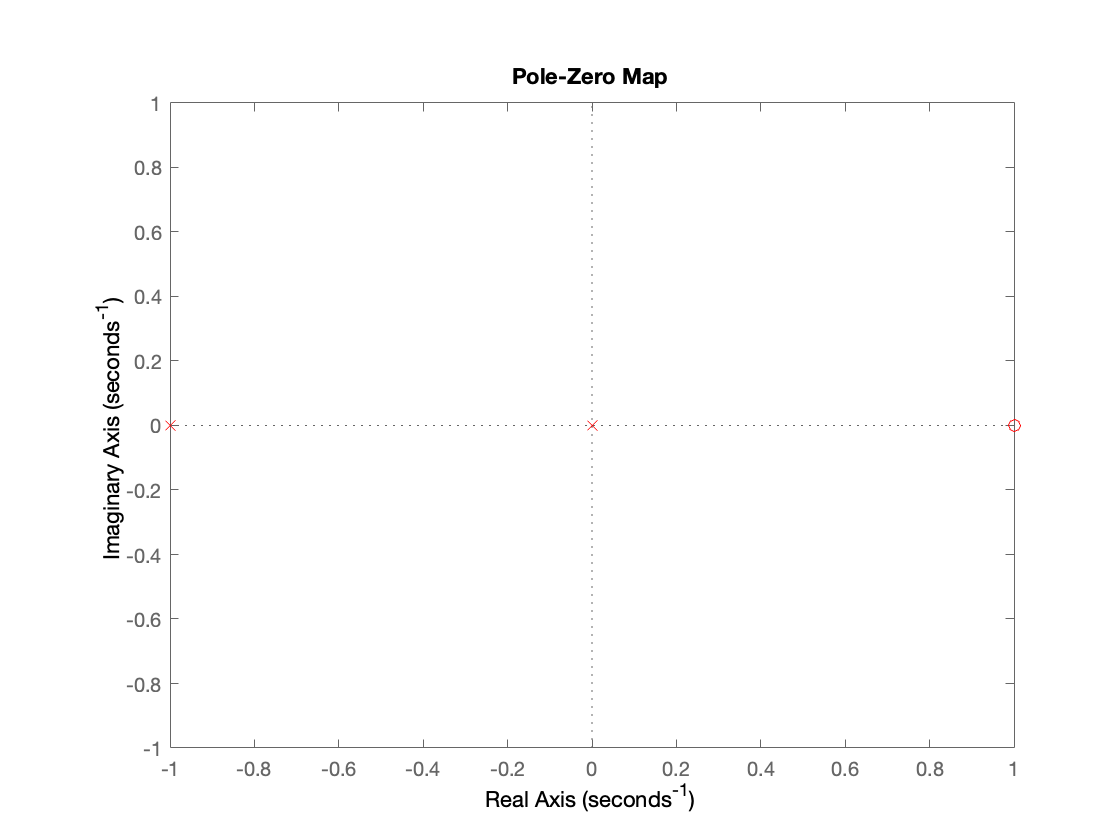

pzplot(T,'r')

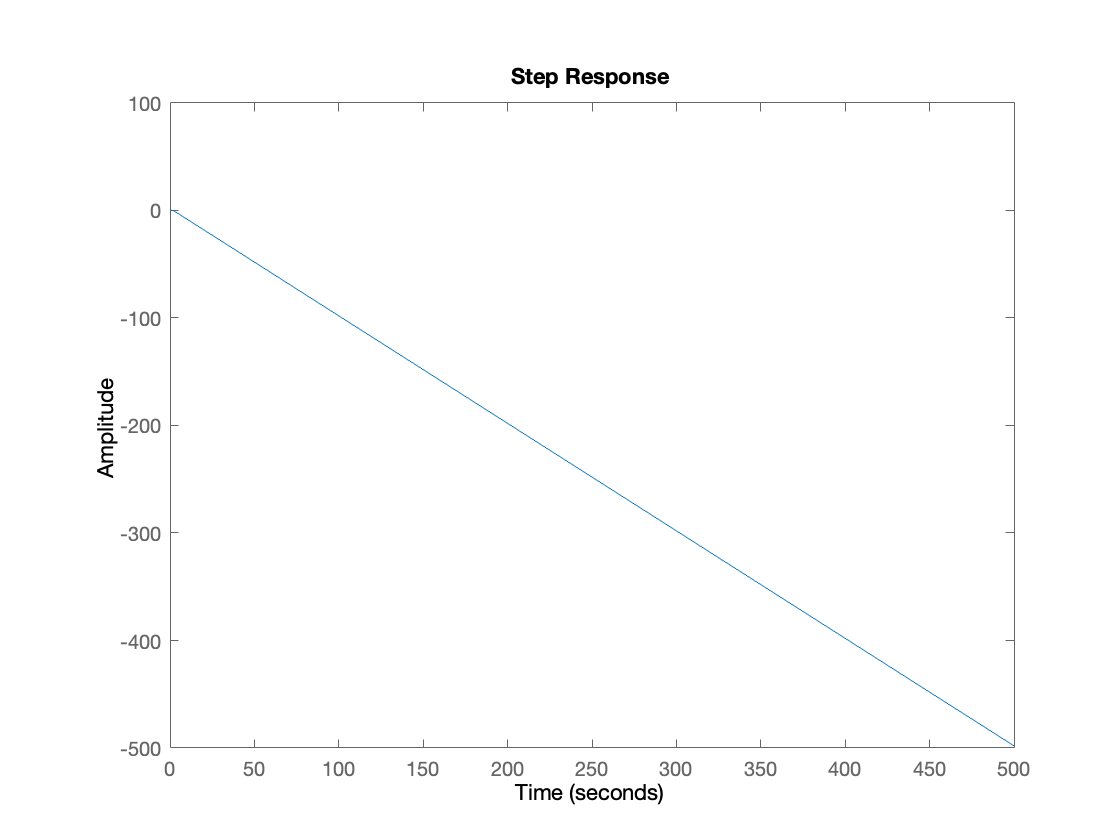

step(T)